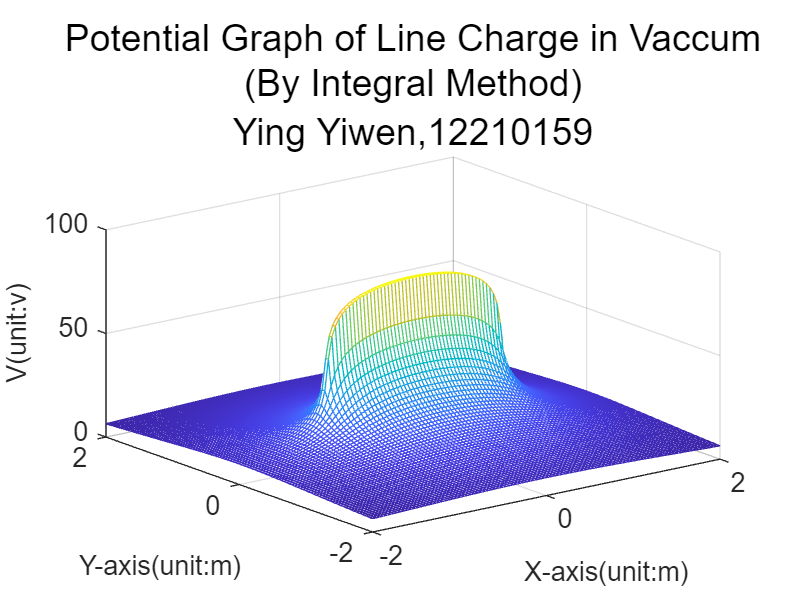

clc,clear,close all;
%by integral
%select region
k=9e9;%electric constant
p=1e-9;%charge density
xm=2;%set x region
ym=2;%set y region
x=linspace(-xm,xm,100);% divide x axis
y=linspace(-ym,ym,100);% divide y axis
[X,Y]=meshgrid(x,y);%form coordinate
r1=1-X+sqrt((1-X).^2+Y.^2);%calculate r1
r2=-1-X+sqrt((-1-X).^2+Y.^2);%calculate r2
V=k.*p.*log(r1./r2);%calculate potential
%draw volt graph
figure;%create figure
mesh(X,Y,V);%draw potential figure
grid on;%set grid on
hold on;%several graphs
%label and title
title(sprintf('Potential Graph of Line Charge in Vaccum\n(By Integral Method)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
zlabel('V(unit:v)','FontSize',10);%zlabel
%save figure
saveas(gcf,'figure1-1.jpg');

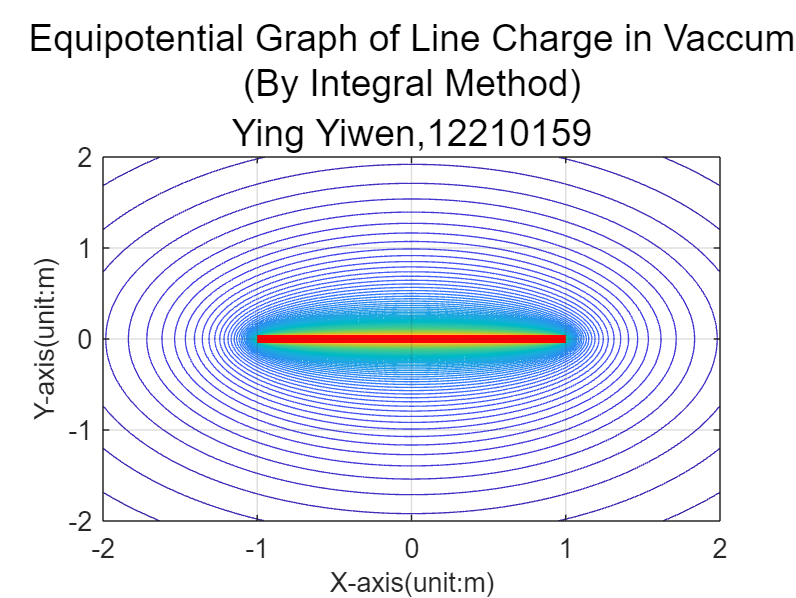

%Select value of equipotential
Vmin=0;%minimum equipotential
Vmax=100;%maximum equipotential
Veq=linspace(Vmin,Vmax,101);%divide equipotential line
%draw equipotential graph
figure;%create figure
contour(X,Y,V,Veq);%draw equipotential figure
grid on;%set grid on
hold on;%several graphs
%label and title
plot([-1,1], [0,0], 'r', 'LineWidth', 3);%draw the line charge
title(sprintf('Equipotential Graph of Line Charge in Vaccum\n(By Integral Method)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
%save figure
saveas(gcf,'figure1-2.jpg');

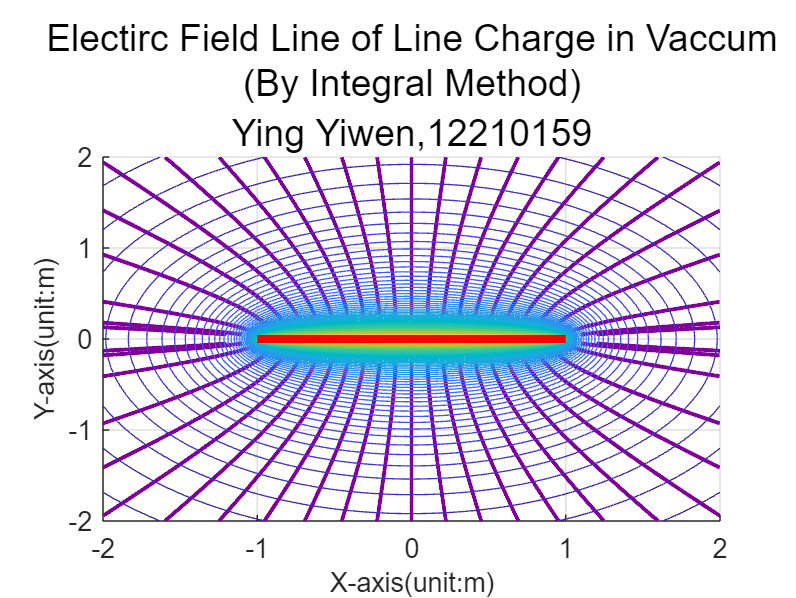

%compute electric field line
[Ex,Ey]=gradient(-V);%compute electric field intensity
del_theta=10;%set division
theta=(0:del_theta:360).*pi/180;%divide angle
xs1=-1.2:0.1:1.2;%compute x value of location 1
xs2=-1.2:0.1:1.2;%compute x value of location 2
ys1=0.05*ones(length(xs1),1);%compute y value of location 1
ys2=-0.05*ones(length(xs1),1);%compute y value of location 2
%Plot the distribution of electric field lines in the field
figure;%create figure
hold on;%several graphs
%label and title
a=streamline(X,Y,Ex,Ey,xs1,ys1);%Electric field line1
set(a,'linewidth',1.5,'color',[0.5,0,0.6]);%set line type
b=streamline(X,Y,Ex,Ey,xs2,ys2);%Electirc field line2
set(b,'linewidth',1.5,'color',[0.5,0,0.6]);%set line type
contour(X,Y,V,Veq);%draw equipotential figure
plot([-1,1], [0,0], 'r', 'LineWidth', 3);%draw the line charge
grid on;%set grid on
title(sprintf('Electirc Field Line of Line Charge in Vaccum\n(By Integral Method)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
%save figure
saveas(gcf,'figure1-3.jpg');%save current figure

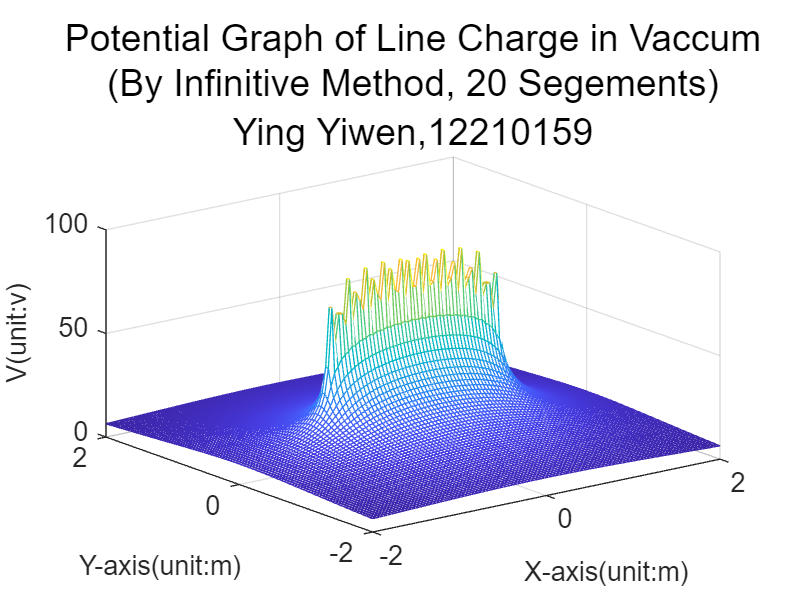

clc,clear,close all;
%by infinitive method,20 parts
%select region
k=9e9;%electric constant
p=1e-9;%charge density
xm=2;%set x region
ym=2;%set y region
x=linspace(-xm,xm,100);% divide x axis
y=linspace(-ym,ym,100);% divide y axis
[X,Y]=meshgrid(x,y);%form coordinate
V=0;
for i = 1:20
    r=sqrt((X-0.1*i+1.05).^2+Y.^2);%compute r of every dx
    V=V+k*p/10./r;%compute V
end
%draw volt graph
figure;%create figure
mesh(X,Y,V);%draw potential figure
grid on;%set grid on
hold on;%several graphs
%label and title
title(sprintf('Potential Graph of Line Charge in Vaccum\n(By Infinitive Method, 20 Segements)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
zlabel('V(unit:v)','FontSize',10);%zlabel
%save figure
saveas(gcf,'figure2-1.jpg');%save current figure

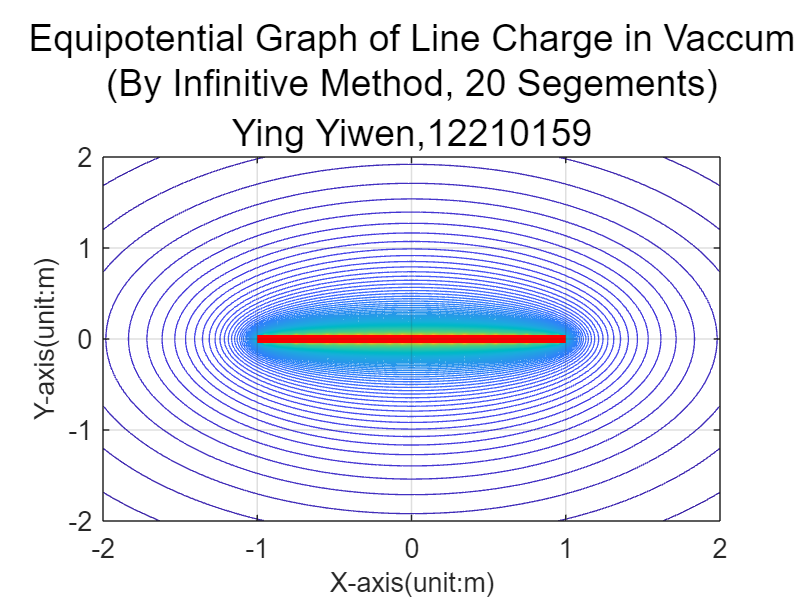

%Select value of equipotential
Vmin=0;%minimum equipotential
Vmax=100;%maximum equipotential
Veq=linspace(Vmin,Vmax,101);%divide equipotential line
%draw equipotential graph
figure;%create figure
contour(X,Y,V,Veq);%draw equipotential figure
grid on;%set grid on
hold on;%several graphs
%label and title
plot([-1,1], [0,0], 'r', 'LineWidth', 3);%draw the line charge
title(sprintf('Equipotential Graph of Line Charge in Vaccum\n(By Infinitive Method, 20 Segements)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
%save figure
saveas(gcf,'figure2-2.jpg');%save current figure

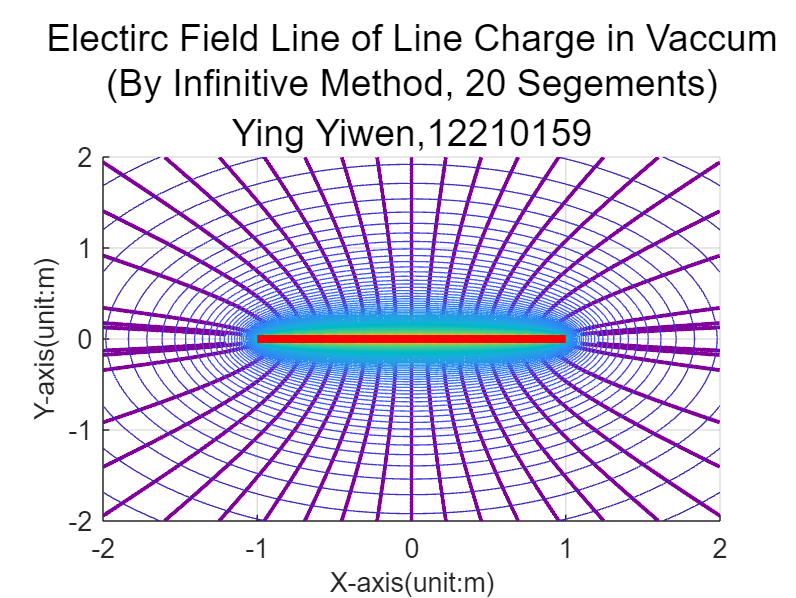

%compute electric field line
[Ex,Ey]=gradient(-V);%compute electric field intensity
del_theta=10;%set division
theta=(0:del_theta:360).*pi/180;%divide angle
xs1=-1.2:0.1:1.2;%compute x value of location 1
xs2=-1.2:0.1:1.2;%compute x value of location 2
ys1=0.05*ones(length(xs1),1);%compute y value of location 1
ys2=-0.05*ones(length(xs1),1);%compute y value of location 2
%Plot the distribution of electric field lines in the field
figure;%create figure
hold on;%several graphs
%label and title
a=streamline(X,Y,Ex,Ey,xs1,ys1);%Electric field line1
set(a,'linewidth',1.5,'color',[0.5,0,0.6]);%set line type
b=streamline(X,Y,Ex,Ey,xs2,ys2);%Electirc field line2
set(b,'linewidth',1.5,'color',[0.5,0,0.6]);%set line type
contour(X,Y,V,Veq);%draw equipotential figure
plot([-1,1], [0,0], 'r', 'LineWidth', 3);%draw the line charge
grid on;%set grid on
title(sprintf('Electirc Field Line of Line Charge in Vaccum\n(By Infinitive Method, 20 Segements)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
%save figure
saveas(gcf,'figure2-3.jpg');%save current figure

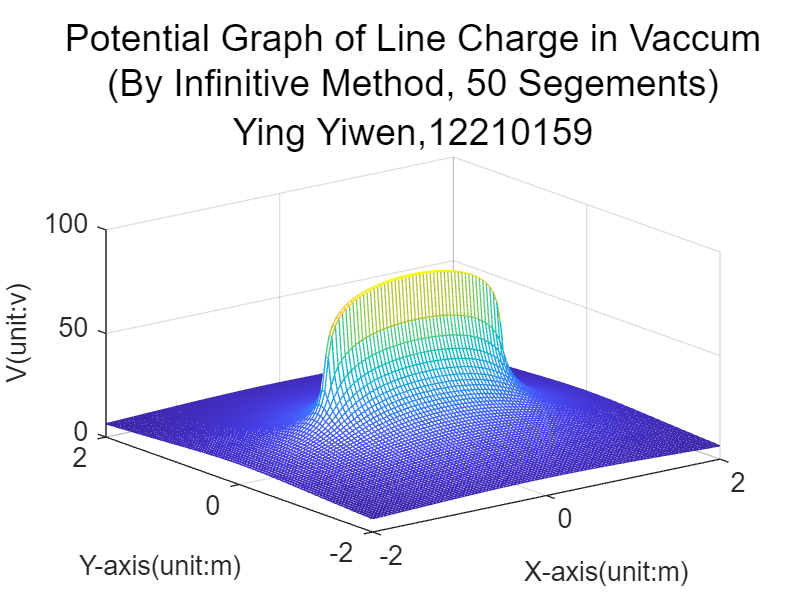

clc,clear,close all;
%by infinitive method,50 parts
%select region
k=9e9;%electric constant
p=1e-9;%charge density
xm=2;%set x region
ym=2;%set y region
x=linspace(-xm,xm,100);% divide x axis
y=linspace(-ym,ym,100);% divide y axis
[X,Y]=meshgrid(x,y);%form coordinate
V=0;
for i = 1:50
    r=sqrt((X-0.04*i+1.02).^2+Y.^2);%compute r of every dx
    V=V+k*p/25./r;%compute V
end
%draw volt graph
figure;%create figure
mesh(X,Y,V);%draw potential figure
grid on;%set grid on
hold on;%several graphs
%label and title
title(sprintf('Potential Graph of Line Charge in Vaccum\n(By Infinitive Method, 50 Segements)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
zlabel('V(unit:v)','FontSize',10);%zlabel
%save figure
saveas(gcf,'figure3-1.jpg');%save current figure

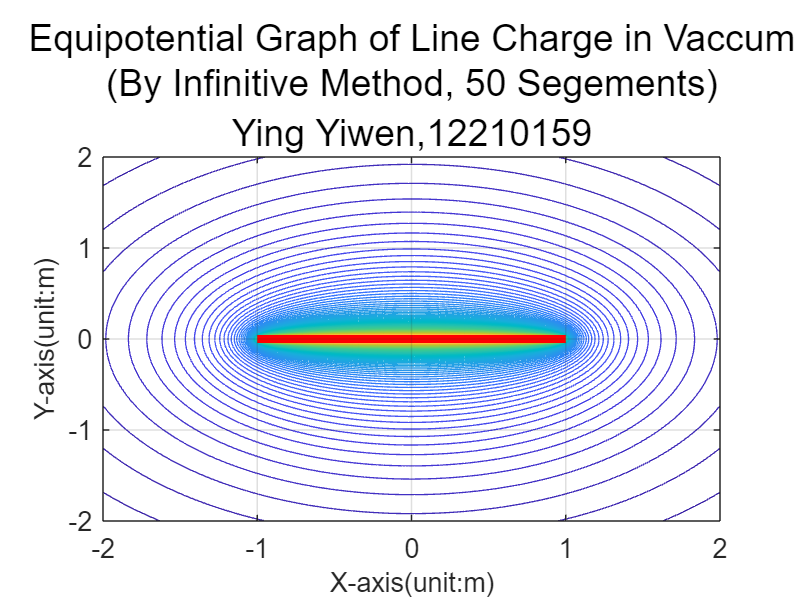

%Select value of equipotential
Vmin=0;%minimum equipotential
Vmax=100;%maximum equipotential
Veq=linspace(Vmin,Vmax,101);%divide equipotential line
%draw equipotential graph
figure;%create figure
contour(X,Y,V,Veq);%draw equipotential figure
grid on;%set grid on
hold on;%several graphs
%label and title
plot([-1,1], [0,0], 'r', 'LineWidth', 3);%draw the line charge
title(sprintf('Equipotential Graph of Line Charge in Vaccum\n(By Infinitive Method, 50 Segements)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
%save figure
saveas(gcf,'figure3-2.jpg');%save current figure

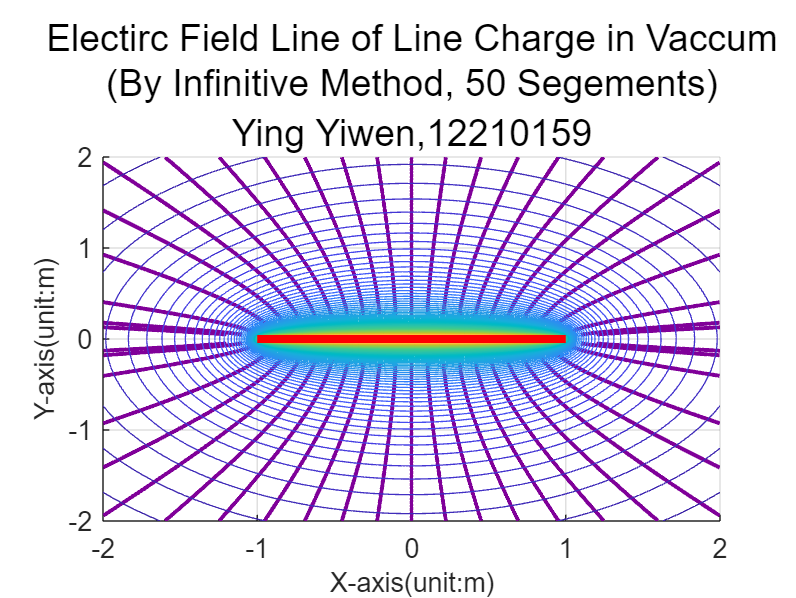

%compute electric field line
[Ex,Ey]=gradient(-V);%compute electric field intensity
del_theta=10;%set division
theta=(0:del_theta:360).*pi/180;%divide angle
xs1=-1.2:0.1:1.2;%compute x value of location 1
xs2=-1.2:0.1:1.2;%compute x value of location 2
ys1=0.05*ones(length(xs1),1);%compute y value of location 1
ys2=-0.05*ones(length(xs1),1);%compute y value of location 2
%Plot the distribution of electric field lines in the field
figure;%create figure
hold on;%several graphs
%label and title
a=streamline(X,Y,Ex,Ey,xs1,ys1);%Electric field line1
set(a,'linewidth',1.5,'color',[0.5,0,0.6]);%set line type
b=streamline(X,Y,Ex,Ey,xs2,ys2);%Electirc field line2
set(b,'linewidth',1.5,'color',[0.5,0,0.6]);%set line type
contour(X,Y,V,Veq);%draw equipotential figure
plot([-1,1], [0,0], 'r', 'LineWidth', 3);%draw the line charge
grid on;%set grid on
title(sprintf('Electirc Field Line of Line Charge in Vaccum\n(By Infinitive Method, 50 Segements)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
%save figure
saveas(gcf,'figure3-3.jpg');%save current figure

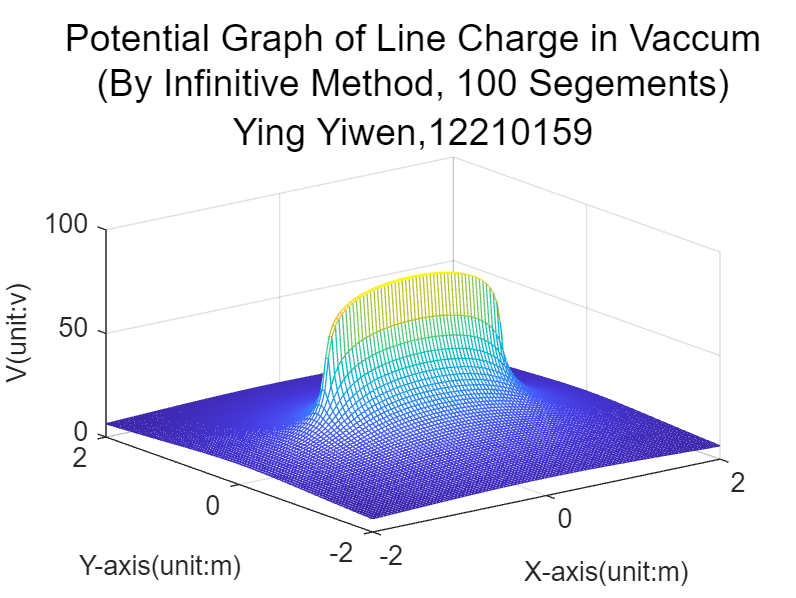

clc,clear,close all;
%by infinitive method,100 parts
%select region
k=9e9;%electric constant
p=1e-9;%charge density
xm=2;%set x region
ym=2;%set y region
x=linspace(-xm,xm,100);% divide x axis
y=linspace(-ym,ym,100);% divide y axis
[X,Y]=meshgrid(x,y);%form coordinate
V=0;
for i = 1:100
    r=sqrt((X-0.02*i+1.01).^2+Y.^2);%compute r of every dx
    V=V+k*p/50./r;%compute V
end
%draw volt graph
figure;%create figure
mesh(X,Y,V);%draw potential figure
grid on;%set grid on
hold on;%several graphs
%label and title
title(sprintf('Potential Graph of Line Charge in Vaccum\n(By Infinitive Method, 100 Segements)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
zlabel('V(unit:v)','FontSize',10);%zlabel
%save figure
saveas(gcf,'figure4-1.jpg');%save current figure

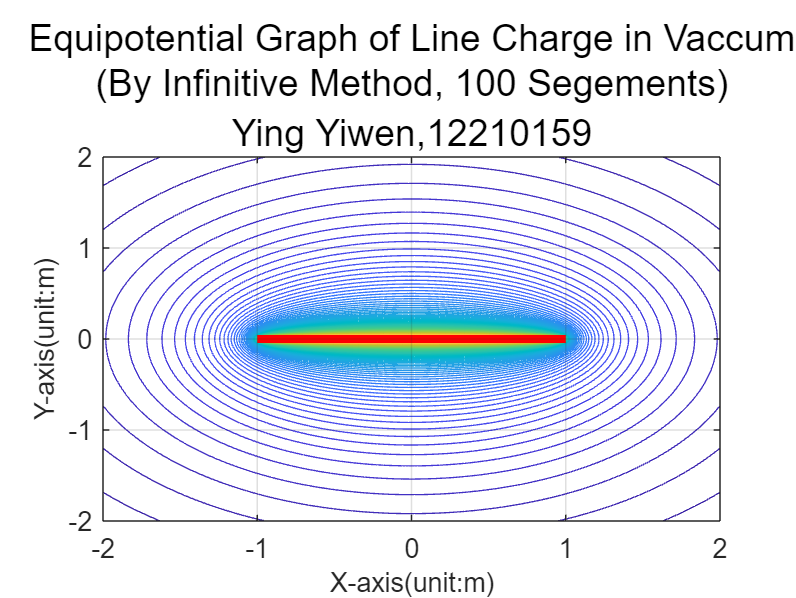

%Select value of equipotential
Vmin=0;%minimum equipotential
Vmax=100;%maximum equipotential
Veq=linspace(Vmin,Vmax,101);%divide equipotential line
%draw equipotential graph
figure;%create figure
contour(X,Y,V,Veq);%draw equipotential figure
grid on;%set grid on
hold on;%several graphs
%label and title
plot([-1,1], [0,0], 'r', 'LineWidth', 3);%draw the line charge
title(sprintf('Equipotential Graph of Line Charge in Vaccum\n(By Infinitive Method, 100 Segements)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
%save figure
saveas(gcf,'figure4-2.jpg');%save current figure

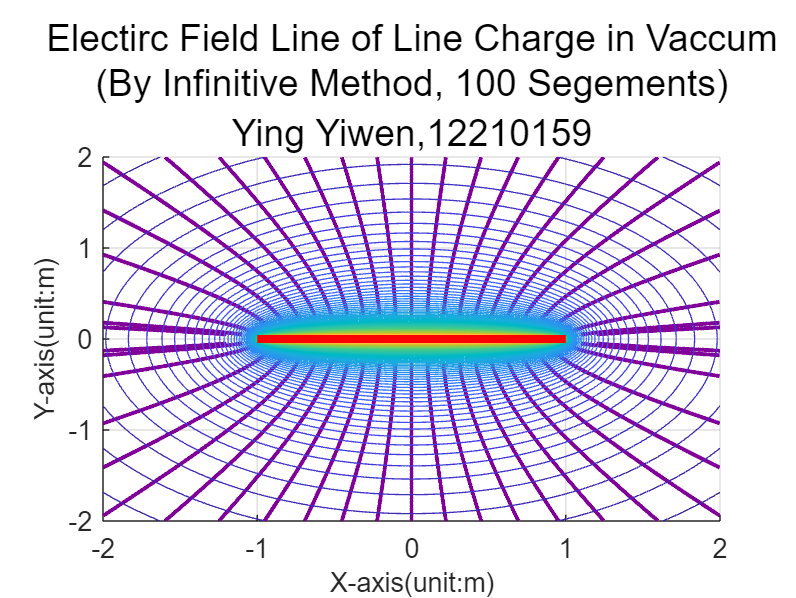

%compute electric field line
[Ex,Ey]=gradient(-V);%compute electric field intensity
del_theta=10;%set division
theta=(0:del_theta:360).*pi/180;%divide angle
xs1=-1.2:0.1:1.2;%compute x value of location 1
xs2=-1.2:0.1:1.2;%compute x value of location 2
ys1=0.05*ones(length(xs1),1);%compute y value of location 1
ys2=-0.05*ones(length(xs1),1);%compute y value of location 2
%Plot the distribution of electric field lines in the field
figure;%create figure
hold on;%several graphs
%label and title
a=streamline(X,Y,Ex,Ey,xs1,ys1);%Electric field line1
set(a,'linewidth',1.5,'color',[0.5,0,0.6]);%set line type
b=streamline(X,Y,Ex,Ey,xs2,ys2);%Electirc field line2
set(b,'linewidth',1.5,'color',[0.5,0,0.6]);%set line type
contour(X,Y,V,Veq);%draw equipotential figure
plot([-1,1], [0,0], 'r', 'LineWidth', 3);%draw the line charge
grid on;%set grid on
title(sprintf('Electirc Field Line of Line Charge in Vaccum\n(By Infinitive Method, 100 Segements)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
%save figure
saveas(gcf,'figure4-3.jpg');%save current figure

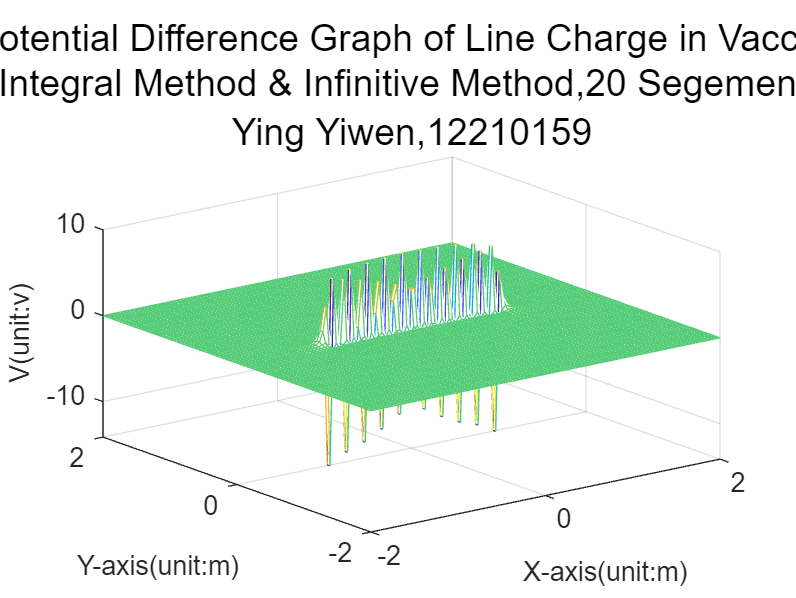

clc,clear,close all;
%difference between integral method and infinitive method with 20 parts
%select region
k=9e9;%electric constant
p=1e-9;%charge density
xm=2;%set x region
ym=2;%set y region
x=linspace(-xm,xm,100);% divide x axis
y=linspace(-ym,ym,100);% divide y axis
[X,Y]=meshgrid(x,y);%form coordinate
%infinitive method, 20 parts
V1=0;
for i = 1:20
    r=sqrt((X-0.1*i+1.05).^2+Y.^2);%compute r of every dx
    V1=V1+k*p/10./r;%compute V
end
%integral method
r1=1-X+sqrt((1-X).^2+Y.^2);%calculate r1
r2=-1-X+sqrt((-1-X).^2+Y.^2);%calculate r2
V2=k.*p.*log(r1./r2);%calculate potential
V=V2-V1;%calculate the difference
%draw volt graph
figure;%create figure
mesh(X,Y,V);%draw potential figure
grid on;%set grid on
%label and title
title(sprintf('Potential Difference Graph of Line Charge in Vaccum\n(Integral Method & Infinitive Method,20 Segements)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
zlabel('V(unit:v)','FontSize',10);%zlabel
%save figure
saveas(gcf,'figure5-1.jpg');%save current figure

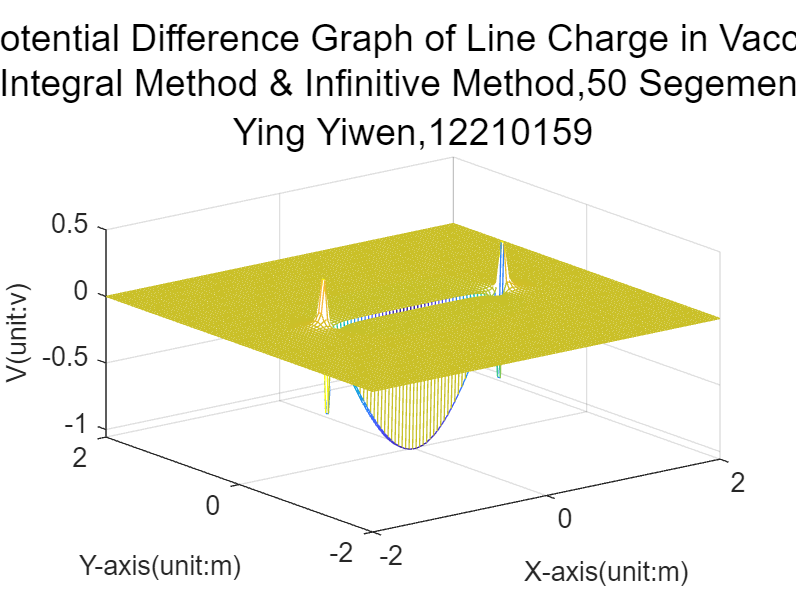

%infinitive method, 50 parts
V1=0;
for i = 1:50
    r=sqrt((X-0.04*i+1.02).^2+Y.^2);%compute r of every dx
    V1=V1+k*p/25./r;%compute V
end
V=V2-V1;%calculate the difference
%draw volt graph
figure;%create figure
mesh(X,Y,V);%draw potential figure
grid on;%set grid on
%label and title
title(sprintf('Potential Difference Graph of Line Charge in Vaccum\n(Integral Method & Infinitive Method,50 Segements)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
zlabel('V(unit:v)','FontSize',10);%zlabel
%save figure
saveas(gcf,'figure5-2.jpg');%save current figure

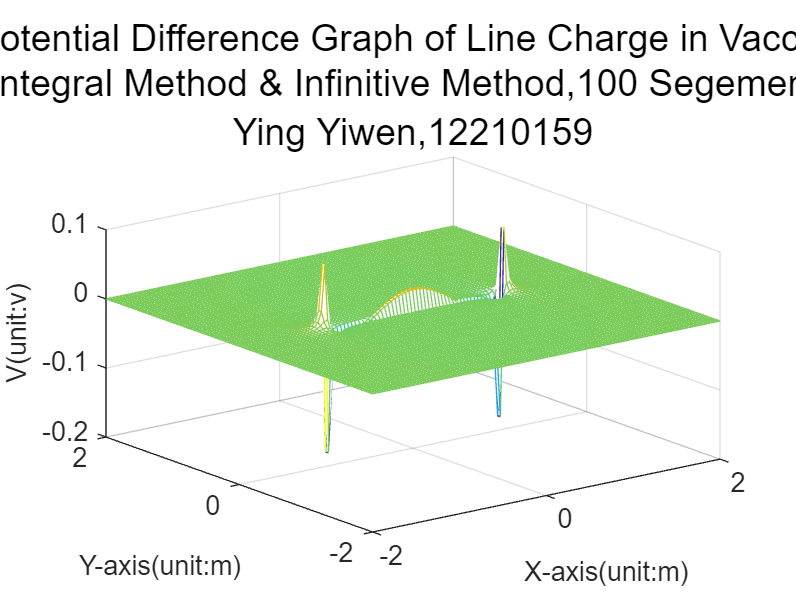

%infinitive method, 100 parts
V1=0;
for i = 1:100
    r=sqrt((X-0.02*i+1.01).^2+Y.^2);%compute r of every dx
    V1=V1+k*p/50./r;%compute V
end
V=V2-V1;%calculate the difference
%draw volt graph
figure;%create figure
mesh(X,Y,V);%draw potential figure
grid on;%set grid on
%label and title
title(sprintf('Potential Difference Graph of Line Charge in Vaccum\n(Integral Method & Infinitive Method,100 Segements)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('X-axis(unit:m)','FontSize',10);%xlabel
ylabel('Y-axis(unit:m)','FontSize',10);%ylabel
zlabel('V(unit:v)','FontSize',10);%zlabel
%save figure
saveas(gcf,'figure5-3.jpg');%save current figure

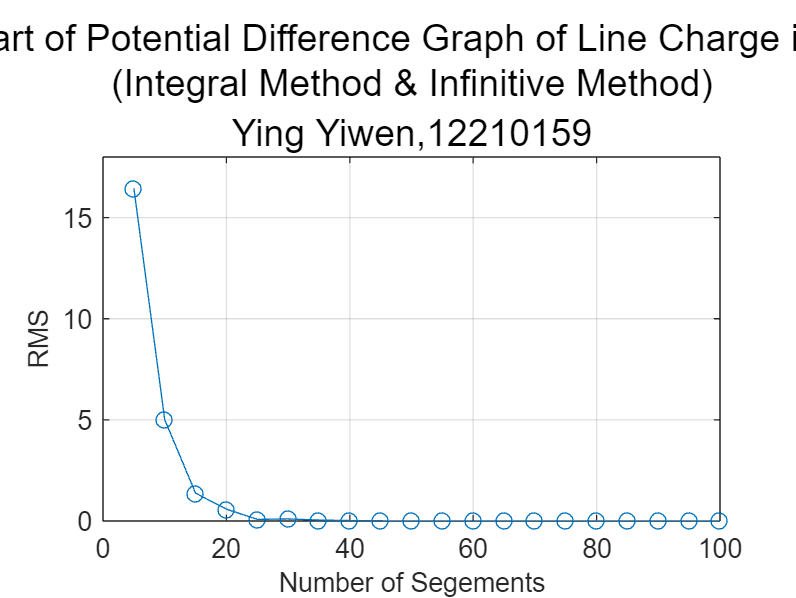

clc,clear,close all;
%draw the difference of various divisons
%select region
k=9e9;%electric constant
p=1e-9;%charge density
xm=2;%set x region
ym=2;%set y region
x=linspace(-xm,xm,100);% divide x axis
y=linspace(-ym,ym,100);% divide y axis
[X,Y]=meshgrid(x,y);%form coordinate
%integral method
r1=1-X+sqrt((1-X).^2+Y.^2);%calculate r1
r2=-1-X+sqrt((-1-X).^2+Y.^2);%calculate r2
V=k.*p.*log(r1./r2);%calculate potential
differ=[];%an array to save the difference
%infinitive method
for i = 5:5:100
    temp=0;
 for j = 1:i
     r=sqrt((X-(2/i)*j+1+(1/i)).^2+Y.^2);%compute r of every dx
     temp=temp+2*k*p/i./r;%compute V
 end
 difference=sum(sum((V-temp).^2))/10000;%compute the total of difference
 differ=[differ difference];
end
x=5:5:100;%x-axis
figure;%create new figure
plot(x, differ, '-o');%plot the line chart
grid on;%set grid on
%label and title
title(sprintf('Line Chart of Potential Difference Graph of Line Charge in Vaccum\n(Integral Method & Infinitive Method)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('Number of Segements','FontSize',10);%xlabel
ylabel('RMS','FontSize',10);%ylabel
%save figure
saveas(gcf,'figure5-4.jpg');%save current figure

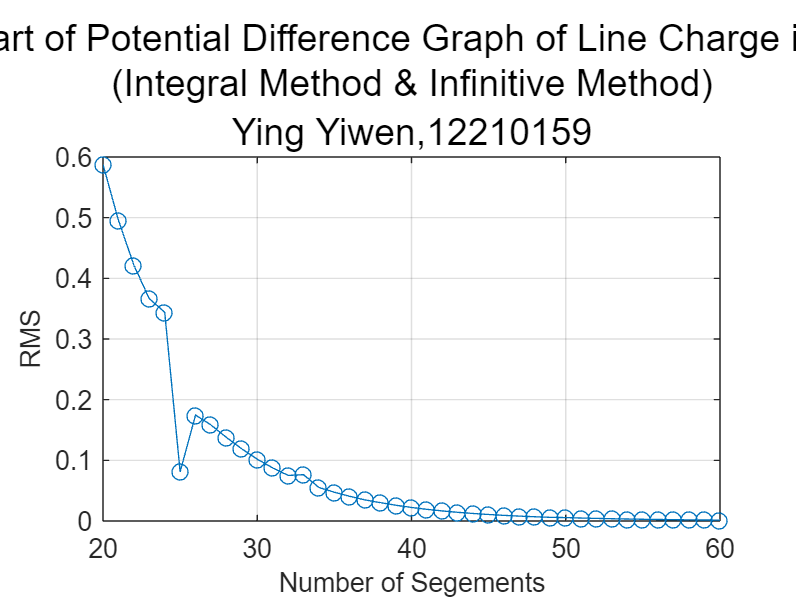

clc,clear,close all;
%draw the difference of various divisons
%select region
k=9e9;%electric constant
p=1e-9;%charge density
xm=2;%set x region
ym=2;%set y region
x=linspace(-xm,xm,100);% divide x axis
y=linspace(-ym,ym,100);% divide y axis
[X,Y]=meshgrid(x,y);%form coordinate
%integral method
r1=1-X+sqrt((1-X).^2+Y.^2);%calculate r1
r2=-1-X+sqrt((-1-X).^2+Y.^2);%calculate r2
V=k.*p.*log(r1./r2);%calculate potential
differ=[];%an array to save the difference
%infinitive method
for i = 20:1:60
    temp=0;
 for j = 1:i
     r=sqrt((X-(2/i)*j+1+(1/i)).^2+Y.^2);%compute r of every dx
     temp=temp+2*k*p/i./r;%compute V
 end
 difference=sum(sum((V-temp).^2))/10000;%compute the total of difference
 differ=[differ difference];
end
x=20:1:60;%x-axis
figure;%create new figure
plot(x, differ, '-o');%plot the line chart
grid on;%set grid on
%label and title
title(sprintf('Line Chart of Potential Difference Graph of Line Charge in Vaccum\n(Integral Method & Infinitive Method)'),'Ying Yiwen,12210159','FontSize',14);%title
xlabel('Number of Segements','FontSize',10);%xlabel
ylabel('RMS','FontSize',10);%ylabel
%save figure
saveas(gcf,'figure5-5.jpg');%save current figure